# Activity 8 Part 2: Logistic Regression

#### PART I: Feature Extraction

I found a dataset online that contains different stages of mango ripening. For the colorspace, I used the Normalized Chromaticity Coordinates (NCC) colorspace for the average red, green, and blue color of the fruit. 

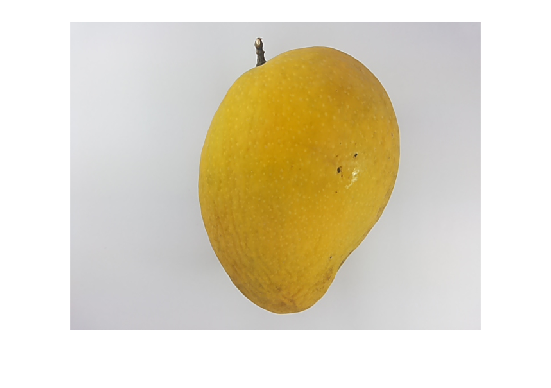

clear;close;
DataSetPath = "c:\Users\Johnenn\OneDrive\Documents\MATLAB\mangoripeness";
ripeFolder = fullfile(DataSetPath,'Train', 'ripe');
unripeFolder = fullfile(DataSetPath,'Train', 'unripe');
%storing the images
ripeImages = imageDatastore(ripeFolder);
unripeImages = imageDatastore(unripeFolder);

numRipeImages = numel(ripeImages.Files);
numUnripeImages = numel(unripeImages.Files);

COLORS = zeros(numRipeImages+numUnripeImages,4); %array of mean RGB colors
COLORS(:,1) = 1;

for i = 1:numRipeImages
    I = readimage(ripeImages, i);
    imshow(I);
    [COLORS(i,2), COLORS(i,3), COLORS(i,4)] = NCCimage(I);
end

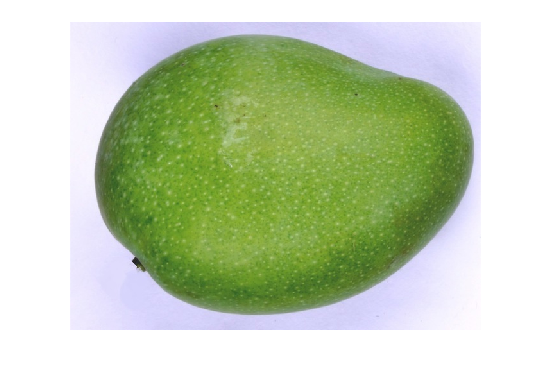

for i = 1:numUnripeImages
    I = readimage(unripeImages, i);
    imshow(I);
    [COLORS(i+numRipeImages,2), COLORS(i+numRipeImages,3), COLORS(i+numRipeImages,4)] = NCCimage(I);
end

#### PART II: Labeling and Weight

For the labeling, the ripe fruits are labeled 1 and the unripe fruits were labeled 0. For the weight, we create a 4x1 array of random numbers.

d = zeros(numRipeImages+numUnripeImages,1);
d(1:numRipeImages) = 1;
w = rand(4,1)*0.01;

#### PART III: Training

eta = 0.01; %learning rate
epochs = 7e5; %training time
beta = 1; %set to 1 

%array for plotting purposes only
A = zeros(numRipeImages+numUnripeImages,1);
Z= zeros(numRipeImages+numUnripeImages,1);

for epoch = 1:epochs

    for i = 1:numRipeImages+numUnripeImages

        a = dot(COLORS(i,:), w); %input
        A(i) = a;
        z = sigmoid((beta*a)); %activation function
        Z(i) = z;
        %weight change rule
        delta_w = eta * (d(i,:) - z) * COLORS(i,:)';
        %update the weight
        w = w + delta_w;
    end
end

Plotting the function.

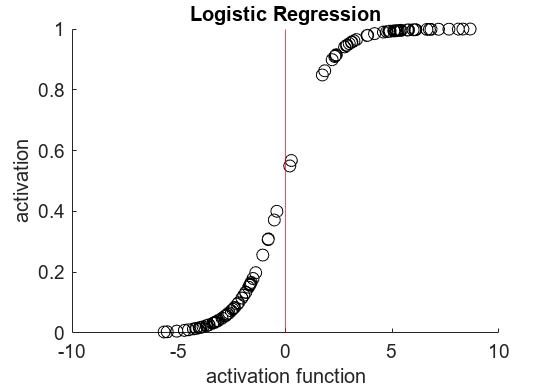

scatter(A(:,1), Z(:,1), 'k');
hold on; 
xlim([-10 10]);
xline(0, 'r');
title('Logistic Regression');
xlabel('activation function');
ylabel('activation');
hold off;

#### PART IV: Testing

DataSetPath = "c:\Users\Johnenn\OneDrive\Documents\MATLAB\mangoripeness"

DataSetPath = "c:\Users\Johnenn\OneDrive\Documents\MATLAB\mangoripeness"

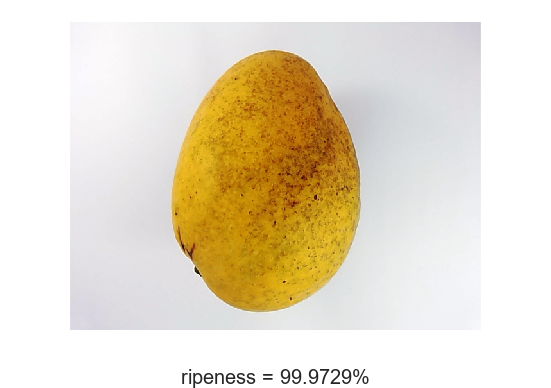

testFolder = fullfile(DataSetPath,'Test');
%storing the images
testImages = imageDatastore(testFolder);
numTestImages = numel(testImages.Files);

%Randomly select picture
R = randi([1 71]);
LogisticRegression(testImages,R, w, 1);

Functions that I used are:

- NCCimage(image) : for the mean NCC values

- NCC(R,G,B): to get the NCC values

- sigmoid(x) : for the activation function 

- LogisticRegression(sample,number,w,beta): for testing 

function [NCC_C_r, NCC_C_g, NCC_C_b] = NCCimage(image)
    I = im2double(image);
    C = im2double(I(220:260,220:260,:));
    CR = double(C(:,:,1));
    CG = double(C(:,:,2));
    CB = double(C(:,:,3));
    [NCC_C_r, NCC_C_g,NCC_C_b] = NCC(CR,CG,CB);
    NCC_C_r = mean2(NCC_C_r);
    NCC_C_g = mean2(NCC_C_g);
    NCC_C_b = mean2(NCC_C_b);
end

function [r,g,b] = NCC(R, G, B)
    %per pixel
    I = R + G + B; 
    
    I(I==0) = 1e5; %to avoid NANs
    
    r = R./I;
    g = G./I;
    b = 1-r-g;
end
function show = LogisticRegression(sample,number,w, beta)
    COLORS = zeros(1,4); %array of mean RGB colors
    COLORS(1,1) = 1;
    I = readimage(sample, number);
    show = imshow(I);
    [COLORS(1,2), COLORS(1,3), COLORS(1,4)] = NCCimage(I);
    a = dot(COLORS,w);
    p = sigmoid((beta*a));
    xlabel(['ripeness = ' num2str(p*100) '%'] );

end

function output = sigmoid(x)
    output = 1 / (1 + exp(-x));
end
